# Network Opinion Manipulation

## Dataset

We are dealing with a direct graph since A is not symetrical.

clear
close all
load("PiecewiseSparse.mat") 
% we are dealing with direct graph problem 

## Model

Dynamic model:


$$X_n ={\bar{A} }^n \cdot X_0 +{\bar{A} }^{n-1} \cdot U_0 +\ldotp \ldotp \ldotp +{\bar{A} }^1 \cdot U_{n-2} +U_{n-1}$$



$$\phi_N =\left\lbrack \begin{array}{ccccc}
{\bar{A} }^{n-1}  & {\bar{A} }^{n-2}  & \cdots  & {\bar{A} }^1  & I_{25} 
\end{array}\right\rbrack$$



$$U_N =\left\lbrack \begin{array}{c}
U_0 \\
U_1 \\
\cdots \;\\
U_{n-1} 
\end{array}\right\rbrack$$



$$X_n ={\bar{A} }^n \cdot X_0 +\phi_N \cdot U_N$$



$$X_n -{\bar{A} }^n \cdot X_0 =\phi_N \cdot U_N$$


formulate a recovery problem with Um a vector with N blocks, each block is s-sparsity

Measurement model Am:


$$\begin{array}{l}
A_{m\;} =\phi {\;}_N \odot M\cdot \left(U\odot U\right)\\
U=\textrm{dctmtx}\left(25\right)\;\\
M:\textrm{each}\;\textrm{row}\;\textrm{is}\;\textrm{sampled}\;\textrm{at}\;\textrm{given}\;\textrm{ratio},\textrm{all}\;\textrm{elements}\in \left\lbrace 0,1\right\rbrace ,\textrm{value}\;1\;\textrm{stands}\;\textrm{for}\;\textrm{chose}\;\textrm{signal}\ldotp 
\end{array}$$


% one realization
% A should be row normalized
A = normr(A);
n = 25;
X_f = FinalState(1, :)';
X_0 = zeros(size(X_f));
phi = zeros(n, n*n);
for i = 1:n
    phi(:, (i-1)*n+1:i*n) = A^(n-i);
end
y = X_f - A^n * X_0;
Am = phi

Am =    -3.1598    1.0029    3.8167   -3.9582    2.4076    2.3067    0.3241   -2.9851    3.6139   -0.2859    4.0699   -5.5093   -2.2553   -0.7965    3.9578    2.9037    2.8262   -0.1326   -2.7969    1.3185   -1.8833   -0.5586    1.7497   -2.5892    3.8586   -0.1970    0.1237   -3.2659    2.6157   -1.9235   -2.2295    0.2654    2.3191   -2.1407   -0.3343   -2.5952    4.1854    0.6242    2.3442   -3.8078   -2.0249   -1.1697    0.6916    3.3515    1.7987    3.6943    3.3023   -1.7537    1.2125   -2.9944
    4.5777   -3.4651    1.5453   -3.3686    0.4396    2.1091    1.0589   -0.0319    0.0382    0.0117   -2.7892   -4.1585    2.3386   -1.2318   -1.7929    1.0748   -5.2720    3.4885   -1.8898   -5.7766   -5.7252   -7.0712   -2.7913   -1.0142   -1.4877   -5.1894    1.8474   -0.5817    1.3282    1.7352   -0.4757   -1.2703   -1.0295    0.4335   -0.8527    3.8242    2.7974   -2.5286   -0.0149    2.0301   -0.0579    5.6829   -1.4197    0.1346    4.9629    4.3955    5.7874    3.6878    0.0794    

## Controllability


$$Rank{[\bar{A} \ I_S]} = Rank{[\bar{A}_{S,:} \ I; \bar{A}_{S^c,:} \ I]}$$


if the $\bar{A}_{S^c} $ is full row rank, then the system is controllable. 

n = 25;
s = 5;
for s = 1:25
    sample_idx = randperm(n, s);
    rest_idx = setdiff(1:n, sample_idx);
    if rank(A(rest_idx, :)) == n-s
        sprintf("when {s = %d}, the system is controllable", s)
    end
end

ans = "when {s = 1}, the system is controllable"

ans = "when {s = 2}, the system is controllable"

ans = "when {s = 3}, the system is controllable"

ans = "when {s = 4}, the system is controllable"

ans = "when {s = 5}, the system is controllable"

ans = "when {s = 6}, the system is controllable"

ans = "when {s = 7}, the system is controllable"

ans = "when {s = 8}, the system is controllable"

ans = "when {s = 9}, the system is controllable"

ans = "when {s = 10}, the system is controllable"

ans = "when {s = 11}, the system is controllable"

ans = "when {s = 12}, the system is controllable"

ans = "when {s = 13}, the system is controllable"

ans = "when {s = 14}, the system is controllable"

ans = "when {s = 15}, the system is controllable"

ans = "when {s = 16}, the system is controllable"

ans = "when {s = 17}, the system is controllable"

ans = "when {s = 18}, the system is controllable"

ans = "when {s = 19}, the system is controllable"

ans = "when {s = 20}, the system is controllable"

ans = "when {s = 21}, the system is controllable"

ans = "when {s = 22}, the system is controllable"

ans = "when {s = 23}, the system is controllable"

ans = "when {s = 24}, the system is controllable"

ans = "when {s = 25}, the system is controllable"

## P-OMP

We use the end iteration condition as:


$$||residual_{25\times1}||_1 < epsilon \cdot ||measurement_{25\times1}||_1 $$


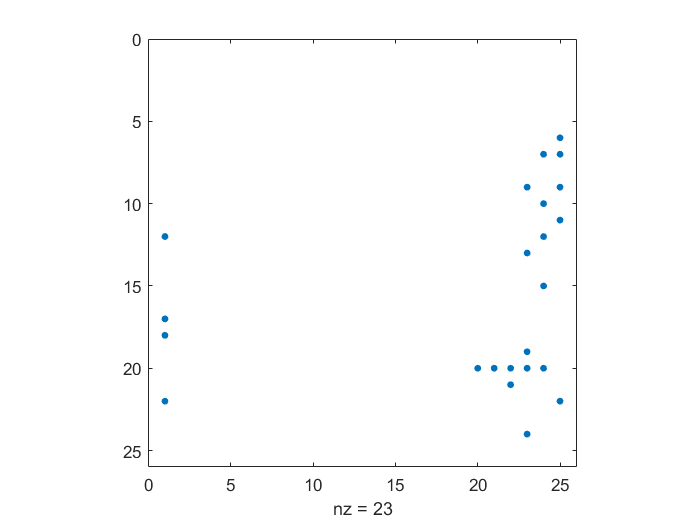

% setting parameters
num_blk = 25;
D = Am(:, (25-num_blk)*25+1:25*25);
y_msmt = FinalState(1, :)';
% total sparsity
sparsity = 5;
K = sparsity * 25; 
% piecewise sparsity
K_i = sparsity * ones(25,1);
% recovery
U = POMP(D, y_msmt, K, K_i, num_blk, 0.01);
spy(U)

## Simulation

During simulation, we need to put additional 0 input to the input matrix. 


$$U_{\textrm{aug}} =\left\lbrack \begin{array}{cc}
U & 0_{25\times 1} 
\end{array}\right\rbrack$$


After running the simulation, the input can drive the system to the given final state. 

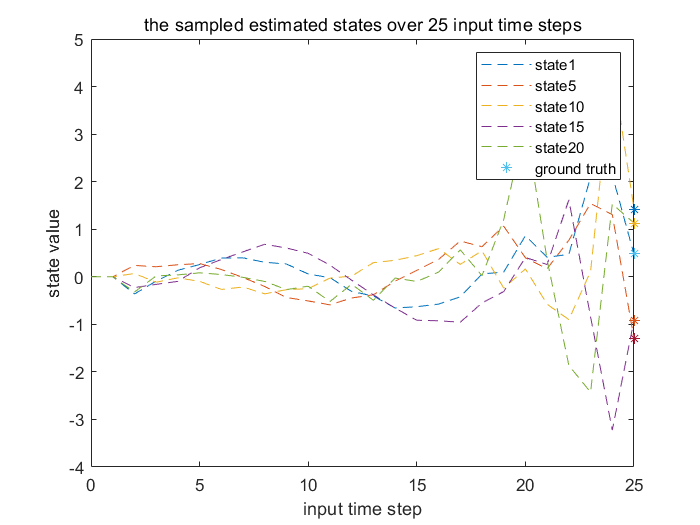

% State space matrix
Ad = A; 
Bd = eye(25);
Cd = eye(25);
Dd = 0;

num_blk = 25;
ts = 1;
t = 0:ts:25;
x0 = zeros(25, 1);
x_f = FinalState(1, :);
U_arg = [U zeros(25, 1)];
sys = ss(Ad, Bd, Cd, Dd, ts);
% simulation
plot_sample_simulation(sys, U_arg, t, x0, x_f, num_blk);

% error = y_msmt - D * rcsct_x(:);
% norm(error, 2)

## Reconstruction error

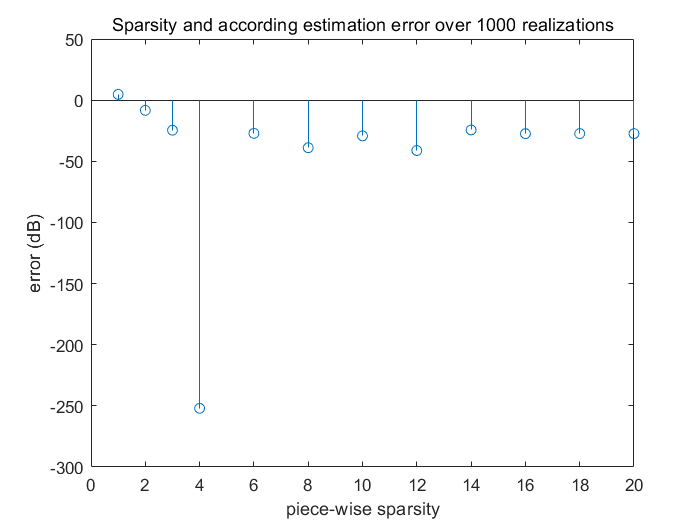

% reconstruction error
piece_sparse = [1 2 3 4 6 8 10 12 14 16 18 20];
err_i = zeros(1,length(FinalState));
err_j = zeros(1,length(piece_sparse));
num_blk = 25;

for j = 1:length(piece_sparse)
    K = piece_sparse(j) * 25;
    K_i = piece_sparse(j) * ones(25,1);
    for i = 1:length(FinalState)
        yl = FinalState(i,:)';
        [u_est, err] = POMP(D, y_msmt, K, K_i, num_blk, 0.01);
        err_i(1,i) = err;
    end
    err_j(1,j) = mean(err_i);
end
% plot
stem(piece_sparse, 20*log10(abs(err_j)))
xlabel("piece-wise sparsity")
ylabel("error (dB)")
title("Sparsity and according estimation error over 1000 realizations")

## Entry limitation

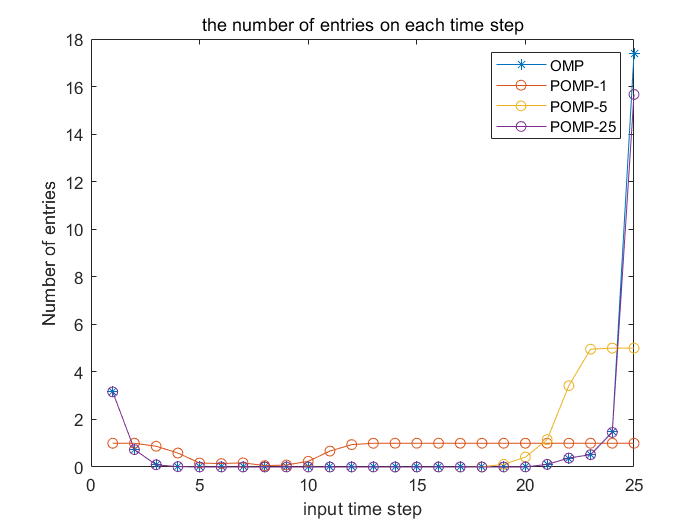

% blockwise entry compare
OMP_entry = zeros(1, 25);
POMP_entry = zeros(3, 25);
% compare 3 different sparsity limiation
piece_sparse = [1 5 25];
% OMP
for i = 1:1000
    y_msmt = FinalState(i, :)';
    [u_omp_est, ~] = OMP(D, y_msmt, num_blk, 0.01);
    % number of nonzero entries on different time step
    OMP_entry(1, :) = OMP_entry(1, :) + sum(u_omp_est ~= 0);
end
OMP_entry(1, :) = OMP_entry(1, :) / 1000;

% POMP
for j = 1:length(piece_sparse)
    K = piece_sparse(j) * 25;
    K_i = piece_sparse(j) * ones(25,1);
    for i = 1:1000
        y_msmt = FinalState(i, :)';
        [u_pomp_est, ~] = POMP(D, y_msmt, K, K_i, num_blk, 0.01);
        % number of nonzero entries on different time step
        POMP_entry(j, :) = POMP_entry(j, :) + sum(u_pomp_est ~= 0);
    end
    % average over 1000 realizations
    POMP_entry(j, :) = POMP_entry(j, :) / 1000;
end
% plot
plot(1:25, OMP_entry, "-*", 1:25, POMP_entry, "-o")
ylabel("Number of entries")
xlabel("input time step");
legend(["OMP", "POMP-1", "POMP-5", "POMP-25"])
title("the number of entries on each time step")

## Relation between total time steps and sparsity

num_successful_rec = zeros(25, 25, 1);
for sparsity = 1:25
    sparsity
    K = sparsity * 25;
    K_i = sparsity * ones(25,1);
    for num_blk = 1:25
        D = Am(:, (25-num_blk)*25+1:25*25);
        for i = 1:50
            x_f = FinalState(i, :)';
            [U, error] = POMP(D, x_f, K, K_i, num_blk, 0.01);
            % if the reconstruction is smalled than 0.1, 
            % it is a successful recovery
            if error < 0.1
                num_successful_rec(sparsity, num_blk) ...
                    = num_successful_rec(sparsity, num_blk) + 1;
            end
        end
    end
end

sparsity = 1

sparsity = 2

sparsity = 3

sparsity = 4

sparsity = 5

sparsity = 6

sparsity = 7

sparsity = 8

sparsity = 9

sparsity = 10

sparsity = 11

sparsity = 12

sparsity = 13

sparsity = 14

sparsity = 15

sparsity = 16

sparsity = 17

sparsity = 18

sparsity = 19

sparsity = 20

sparsity = 21

sparsity = 22

sparsity = 23

sparsity = 24

sparsity = 25

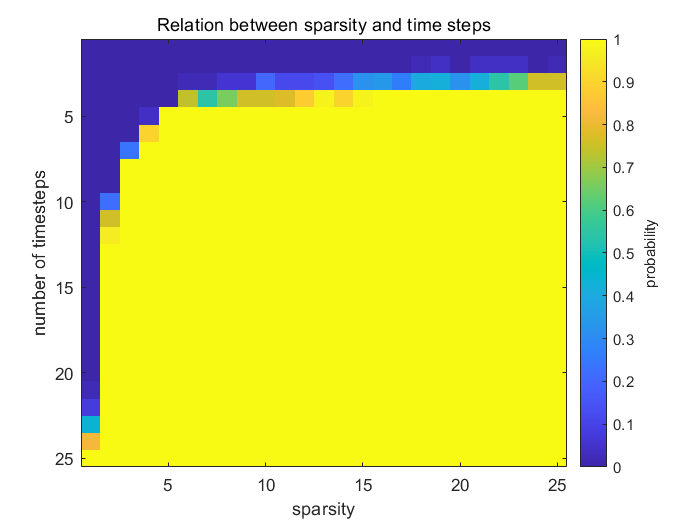

num_successful_rec = num_successful_rec / 50;
% plot
imagesc(num_successful_rec(:,:,1))
ylabel(colorbar, 'probability');
xlabel("sparsity");
ylabel("number of timesteps");
title("Relation between sparsity and time steps")

## Control effort

% blockwise entry compare
OMP_energy = zeros(1, 25);
POMP_energy = zeros(3, 25);

piece_sparse = [3 5 10];
% OMP

for num_blk = 10:25
    D = Am(:, (25-num_blk)*25+1:25*25);
    for i = 1:100
        y_msmt = FinalState(i, :)';
        [u_omp_est, ~] = OMP(D, y_msmt, num_blk, 0.01);
        % use L2-norm to compute the energy of matrix
        OMP_energy(:, num_blk) = OMP_energy(:, num_blk) + norm(u_omp_est, 2);
    end
end
OMP_energy = OMP_energy / 100;

% POMP
for j = 1:length(piece_sparse)
    K = piece_sparse(j) * 25;
    K_i = piece_sparse(j) * ones(25,1);
    for num_blk = 10:25
        D = Am(:, (25-num_blk)*25+1:25*25);
        for i = 1:100
            y_msmt = FinalState(i, :)';
            [u_pomp_est, ~] = POMP(D, y_msmt, K, K_i, num_blk, 0.01);
            POMP_energy(j, num_blk) = POMP_energy(j, num_blk) + norm(u_pomp_est, 2);
        end
    end
end
POMP_energy = POMP_energy / 100;
% plot
plot(10:25, OMP_energy(:, 10:25), "-*", 10:25, POMP_energy(:, 10:25), "-o")
ylabel("Control effort")
xlabel("Number of steps");
legend(["OMP", "POMP-3", "POMP-5", "POMP-10"])
title("Relation between number of steps and control effort")


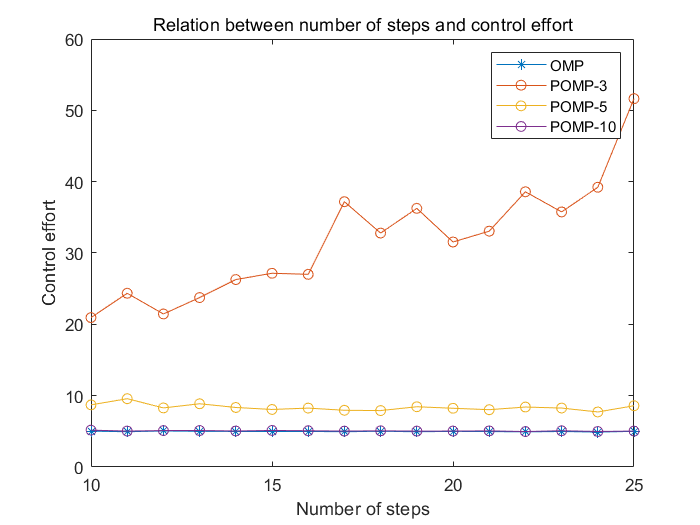

function y = plot_sample_simulation(sys, U_arg, tspan, x0, x_f, num_steps)
    [y, t, ~] = lsim(sys, U_arg', tspan, x0);

    sample_idx = [1, 5, 10, 15, 20];
    plot(t, y(:, sample_idx), "--", num_steps, x_f(sample_idx), "*");
    % error_sim = x_f - y(num_steps+1, :)';
    % disp(norm(error_sim, 2));
    legend(["state1", "state5", "state10", "state15", "state20", "ground truth"]);
    xlabel("input time step");
    ylabel("state value");
    str = sprintf("the sampled estimated states over %d input time steps", num_steps);
    title(str)
end

function [y, error] = POMP(D, y_msmt, K, K_i, num_blk, eps)
    % input
    % % D:matrix -- Measurement matrix
    % % y_msmt:vector -- measurement
    % % K:int -- sparsity bound
    % % K_i:vector -- piecewise sparsity
    % % eps:float -- end iteration condition
    % output
    % % y:matrix -- reconstructed matrix
    % % error: float -- L2 norm of residual
    
    % initialize
    L = num_blk;
    spt = zeros(1, L*25);
    abdn = zeros(1, L*25);
    resd = y_msmt; % residual, x0 = 0
    ptr1 = 1; % pointer of support set
    ptr2 = 1; % pointer of abondon set
    U = 1:L*25; % universal set
    block_count = zeros(L, 1); % to track the entry in each block
    
    vec_s0 = zeros(L*25, 1);
    vec_s = vec_s0;
    % iteration
    for k = 1:1000
        avlb = setdiff(U, abdn(1:ptr2));
        D_k = D(:, avlb);
        h_k = D_k' * resd;
        [~, max_idx] = max(abs(h_k));
        omega_k = find_in_original(D, D_k(:, max_idx)');
        spt(ptr1) = omega_k;
        ptr1 = ptr1 + 1;
        % block-wise
        block_idx = in_which_block(omega_k, 25);
        block_count(block_idx) = block_count(block_idx) + 1;
        if block_count(block_idx) == K_i(block_idx)
            % abondan the element from the block
            blk_h = 25 * (block_idx - 1) + 1; blk_t = 25 * block_idx;
            blk_abdn = setdiff(U(blk_h:blk_t), spt(1:ptr1-1)); 
            for j = 1:length(blk_abdn)
                abdn(ptr2) = blk_abdn(j);
                ptr2 = ptr2 + 1;
            end
        end
        D_s = D(:, spt(1:ptr1-1));
        DD_s = D_s'*D_s;
        % prevent the singular precision to burden the iteration speed
        if det(DD_s) <= 1e-15
            break
        end
        vec_s(spt(1:ptr1-1)) = (DD_s) \ D_s' * y_msmt;
        resd = y_msmt - D * vec_s;
        % norm(resd, 2)
        if (norm(resd, 2) < eps * norm(y_msmt, 2)) || (ptr1-1 >= K)
            break
        end
    end
    error = norm(resd, 2);
    y = reshape(vec_s, [25, num_blk]);
end

% supporting function
function y = in_which_block(omega, bs)
    % loacte the block of the vector
    y = ceil(omega / bs); 
end
function column=find_in_original(M, v)
    % find the vector row index on the original matrix
    tf = ismember(M', v, "rows");
    column = find(tf);
end

% OMP function
function y = diagonal(A, r)
    y = find(abs(A'*r) == max(abs(A'*r)));
end

function [rcsct_x, error] = OMP(A, y_msmt, p_size, e)
    % initialization
    othg_idx = zeros(p_size*25, 1);
    ptr = 1;
    vec_z0 = zeros(p_size*25, 1);
    vec_z = vec_z0;
    resd = y_msmt;
    for i = 1:1000
        k = diagonal(A, resd);
        if ~ismember(k, othg_idx)
            othg_idx(ptr) = k;
            ptr = ptr + 1;
        end
        A_othg = A(:, othg_idx(1:ptr-1));
        vec_z(othg_idx(1:ptr-1)) = (A_othg'*A_othg) \ A_othg' * y_msmt;
        resd = y_msmt - A * vec_z;
        % stopping criteria
        if norm(resd) < e
            break;
        end
    end
    error = norm(resd);
    % reshape the vector
    rcsct_x = reshape(vec_z, [25, p_size]);
end


